# Estimating cone fundamentals from color matching functions

We show how to use the color matching functions of dichromatic subjects to estimate the cone fundamentals.  

The assumptions are these.

- Dichromats and color normals have the same cones;  each of the three types of dichromats is missing one of the three types of cones

- The color matching functions are a linear transformation away from the cone fundamentals

The insight is to use geometry and linear algebra as follows.  Suppose that the three cone fundamentals of a normal are C = [L,M,S].  The fundamentals for a protanope are [M,S], for a deuteranope are [L,S] and for a tritanope are [L,M].

The color-matching functions of the dichromatis are spanned by only two vectors; thus they form a plane in wavelength-space.  I can't plot all the dimensions for wavelength, but intuitively we can show the plane for, say, a deuteranope and the plane for a tritanope.  

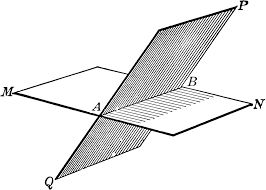

The deuteranope ([L,S], and tritanope ([L,M]) share one dimension, the L-cone dimension.  So the intersection of the two planes must be the L-cone fundamental.  Similarly, we can compare the two other dichromatic combinations to estimate each of the three cone types.

One of the more surprising aspects of the calculation is that we can do this calculation from the color matching functions, without knowing any of the fundamentals.  The geometric intuition is simple: the color-matching functions span the same plane as the cone fundamentals, and we are estimating the intersection of the planes.  So, knowing only the color-matching functions we can compute all three color fundamentals.  Very cool!

## Read in the fundamentals

Read the standard cone fundamentals (LMS) compiled by Andrew Stockman.

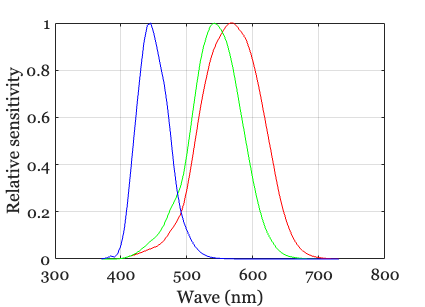

[LMS,wave] = ieReadSpectra('StockmanEnergy');

ieNewGraphWin;
plot(wave,LMS); 
xlabel('Wave (nm)'); ylabel('Relative sensitivity'); grid on

## Simulated CMFs for the three types of dichromats

We apply a linear transform (M1, M2 or M3) to the protan/deutan/tritan fundamentals to simulate the CMFs. Notice that we use a different linear transform for each of the deuteranopic CMFs.  Even so, the calculation still solves. 

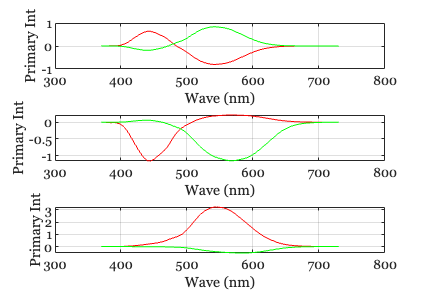

M1 = randn(2,2);
M2 = randn(2,2);
M3 = randn(2,2);

% We check that L,M and N are invertible
assert(max2(M1\M1 - eye(2)) < 1e-10)
assert(max2(M2\M2 - eye(2)) < 1e-10)
assert(max2(M3\M3 - eye(2)) < 1e-10)

% These are the synthetic CMFs of the three types of deuteranopes
ieNewGraphWin;
MS = LMS(:,2:3)*M1;
subplot(3,1,1)
plot(wave,MS);grid on; xlabel('Wave (nm)'); ylabel('Primary Int')

LS = LMS(:,[1,3])*M2;
subplot(3,1,2);
plot(wave,LS);grid on; xlabel('Wave (nm)'); ylabel('Primary Int')

LM = LMS(:,1:2)*M3;
subplot(3,1,3);
plot(wave,LM); grid on; xlabel('Wave (nm)'); ylabel('Primary Int')

## The intersection of planes

We solve for the intersection of the two planes using this simple linear algebraic.

Create a matrix that has the CMFs of one type of dichromatic in the first two columns and the CMFS of a second type of dichromat in the second two columns.  The intersection will specified by finding a four-dimensional vector, n, such that


$$0=X\;n$$


For this vector, the weighted sum of the first two columns (the weights are (1,2)) must be the negative of the weighted sum of the third and fourth columns (n(3,4)).  That vector is in the intersection of the two planes!

We find the solution to the equation from the singular value decomposition, using the Matlab function 'null', which returns the null space of the matrix X.

### L-Cone

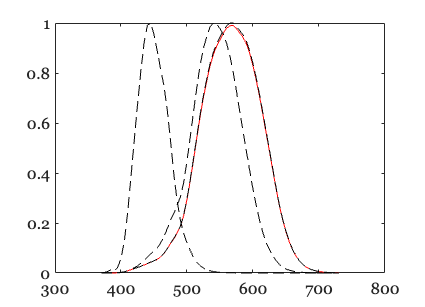

X = [LS,LM];  % L-cone

% Find the solution, n, to 0 = X n
n = null(X); 
est = X(:,[1,2])*n(1:2);

% Make the estimate positive for convenience
if sum(est) < 0, est = -1*est; end
est = ieScale(est,1);

%{ 
% Check that the sum of the third and fourth is the same (up to sign) this way
 est2 = X(:,[3,4])*n(3:4);
 if sum(est2) < 0, est = -1*est2; end
 est2 = ieScale(est2,1);
 ieNewGraphWin, plot(est(:),est2(:),'.');
 identityLine;
%} 

% Plot the estimate and compare with the original
% The 0.99 makes the overlay visible
ieNewGraphWin;
plot(wave,0.99*est,'r-',wave,LMS,'k--');

### M-cone

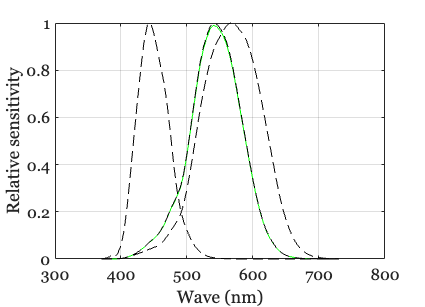

X = [MS,LM]; 

% Find the solution, n, to 0 = X n
n = null(X); 
est = X(:,[1,2])*n(1:2);

% Make the estimate positive
if sum(est) < 0, est = -1*est; end
est = ieScale(est,1);
ieNewGraphWin;
plot(wave,0.99*est,'g-',wave,LMS,'k--');
xlabel('Wave (nm)'); ylabel('Relative sensitivity'); grid on;

### S-cone

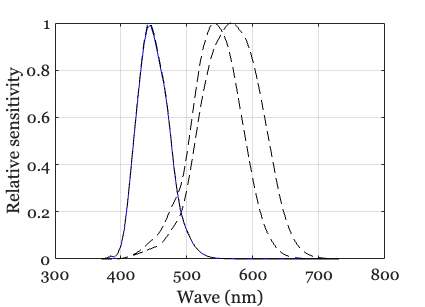

X = [MS,LS];

% Find the solution, n, to 0 = X n
n = null(X); 
est = X(:,[1,2])*n(1:2);

% Make the estimate positive
if sum(est) < 0, est = -1*est; end
est = ieScale(est,1);
ieNewGraphWin;
plot(wave,0.99*est,'b-',wave,LMS,'k--');
xlabel('Wave (nm)'); ylabel('Relative sensitivity'); grid on;